# HMM Analysis

clear % clear all variables in the workspace
close all % close any figure windows that might be open
clc

addpath(genpath('./lib'))

Figflag = 0;
cmap_temp = [[0 0.4470 0.7410];[0.8500 0.3250 0.0980];[0.9290 0.6940 0.1250];[0.4940 0.1840 0.5560]];

## Part 1: Add working path and load the data

We will initialize the paths that are used later

% Make figure path
FigPath = ['./figure/embryo6/'];
mkdir(FigPath)

Now, load all the data

load('./data/hmm_input_output.mat')

Specify some parameters

numParticle = length(hmm_input_output);
TimeOffset = 11.31;

% Specify the bins we want to plot
%binRange = 61:66; % 61-66 
binRange = 62:66; % new

%bin number
len = 15;

%time range to plot
TimeMin = 300;
TimeMax = 1800;

offset = 1.8E5;
%edges = linspace(2.6E5,4.4E5,len+1);
edges = linspace(2.6E5-offset,4.4E5-offset,len+1);

## Part 2: Filter traces including quality control

First, we want to filter the traces based on SetID

dataID = 2; % We want to analyze "optoknirps_new_embryo6"
SetID_all = [hmm_input_output(:).SetID]; % SetID for all the traces
%TraceIndex = find(SetID_all == dataID); % Trace index that we will analyze

Then, we can assign the traces to each AP bin

APbinID = linspace(0,100,101);
APPosition_mean = zeros(numParticle,1);

for i = 1:numParticle
    APPosition_mean(i) = mean(hmm_input_output(i).APPosition);
end

APbinData = discretize(APPosition_mean,APbinID);

Quality control: Only keep the traces that is continuous across specified time range

QualityFlag = zeros(numParticle,1);

LeftBound = 5;
RightBound = 15;

for i = 1:numParticle
    MinTime = hmm_input_output(i).Time(1)/60-TimeOffset;
    MaxTime = hmm_input_output(i).Time(end)/60-TimeOffset;

    if (MinTime<LeftBound) && (MaxTime>RightBound)
        QualityFlag(i) = 1;
    else
        QualityFlag(i) = 0;
    end
end

## Part 3: Compile promoter states

First, we will do this for the full bin range

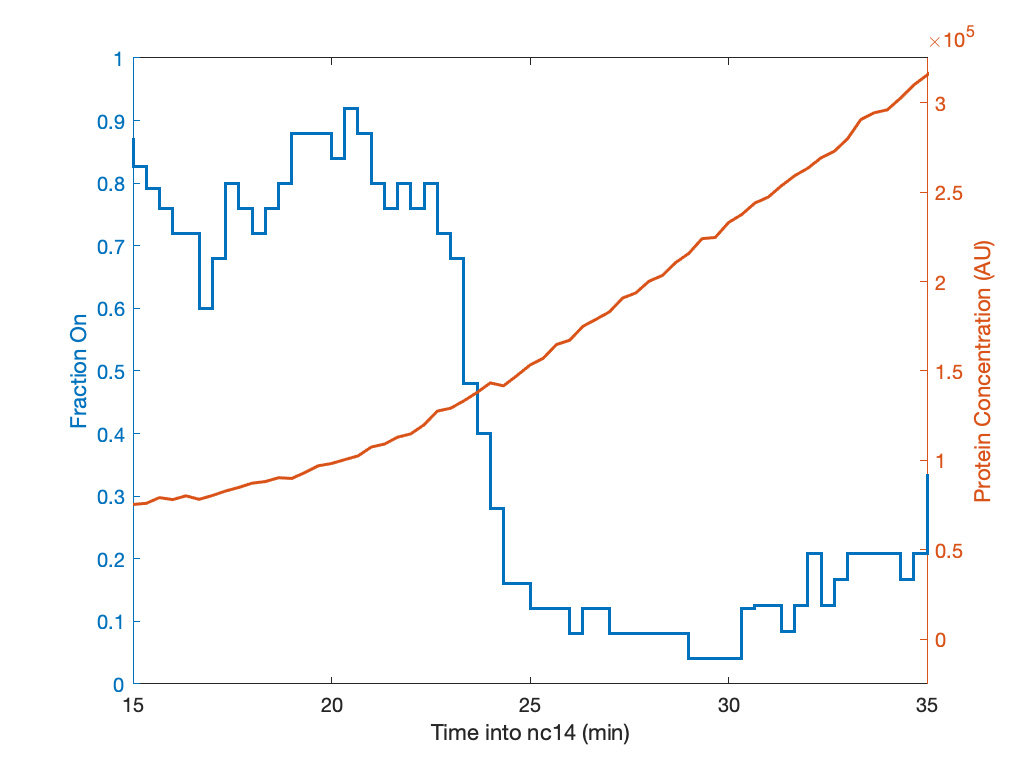

TimeRange = 0:20:2400;

% Initialize array for storage
TotalOn = zeros(1,length(TimeRange));
TotalTrace = zeros(1,length(TimeRange));
ProteinSum = zeros(1,length(TimeRange));
SpotSum = zeros(1,length(TimeRange));

TraceIndex = find((SetID_all == dataID) & (ismember(APbinData,binRange)') & QualityFlag');

% compile promoter states and protein concentration
for i = TraceIndex
    TimePoint = hmm_input_output(i).Time;
    PromoterState = hmm_input_output(i).PromoterState;
    NuclearConc = hmm_input_output(i).NuclearKnirps-offset;
    SpotFluo = hmm_input_output(i).SpotFluorescence;
    
    for j = 1:length(TimePoint)
        Index = find(TimeRange==TimePoint(j));
        % compile promoter states
        if PromoterState(j)>2
            TotalOn(Index) = TotalOn(Index)+1;
            TotalTrace(Index) = TotalTrace(Index)+1;
        else
            TotalTrace(Index) = TotalTrace(Index)+1;
        end
        % compile protein concentration
        ProteinSum(Index) = ProteinSum(Index)+NuclearConc(j);
        SpotSum(Index) = SpotSum(Index)+SpotFluo(j);
    end
    
end

FractionOn = TotalOn./TotalTrace;
SpotAvr = SpotSum./TotalTrace;
ProteinAvr = ProteinSum./TotalTrace;

fig = figure;
yyaxis left
stairs(TimeRange/60,FractionOn,'LineWidth',1.5)
ylabel('Fraction On')
ylim([0 1])
yyaxis right
plot(TimeRange/60,ProteinAvr,'LineWidth',1.5)
ylabel('Protein Concentration (AU)')
ylim([2E5 5.5E5]-2.25E5)

xlim([15,35])
xlabel('Time into nc14 (min)')

We can plot "input-output" function for it

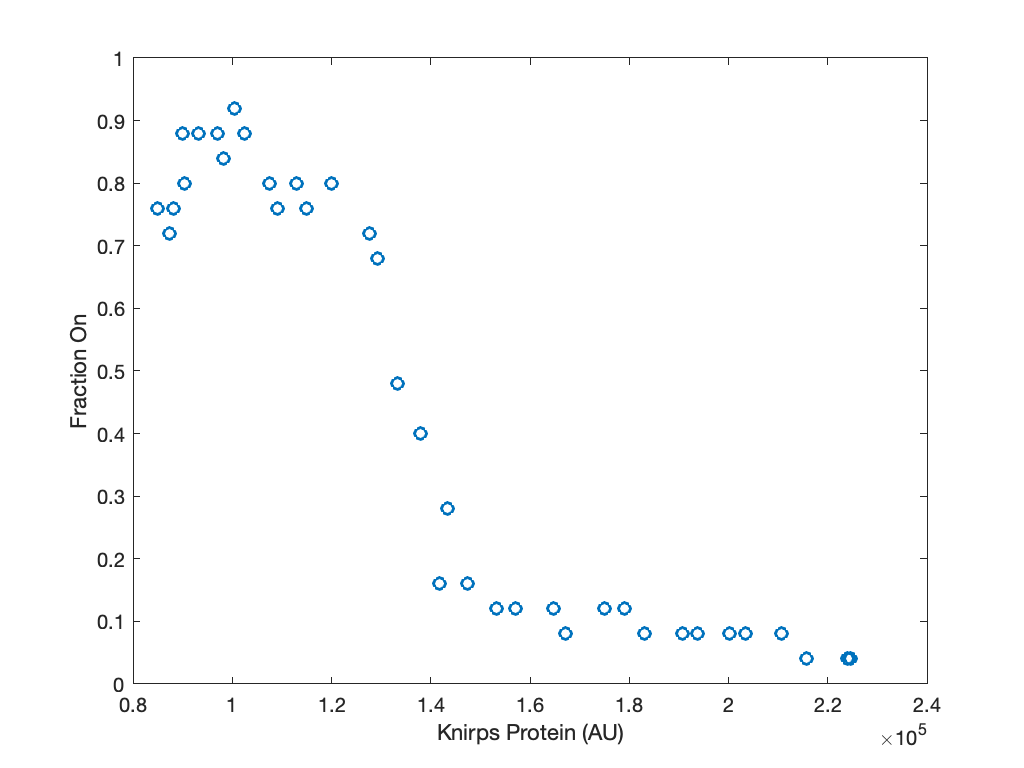

TimePlotRange = 54:90;

% generate fit
%fitname = 'a*x^n/(K^n+x^n)';

% without c
%[io_fit_full,gof_full] = fit(x(:),y(:),fitname,'StartPoint',[9e5,8e4,0],'Lower',[0,0,0]);


Fig = figure;
plot(ProteinAvr(TimePlotRange),FractionOn(TimePlotRange),'o','LineWidth',1.5)
xlabel('Knirps Protein (AU)')
ylabel('Fraction On')

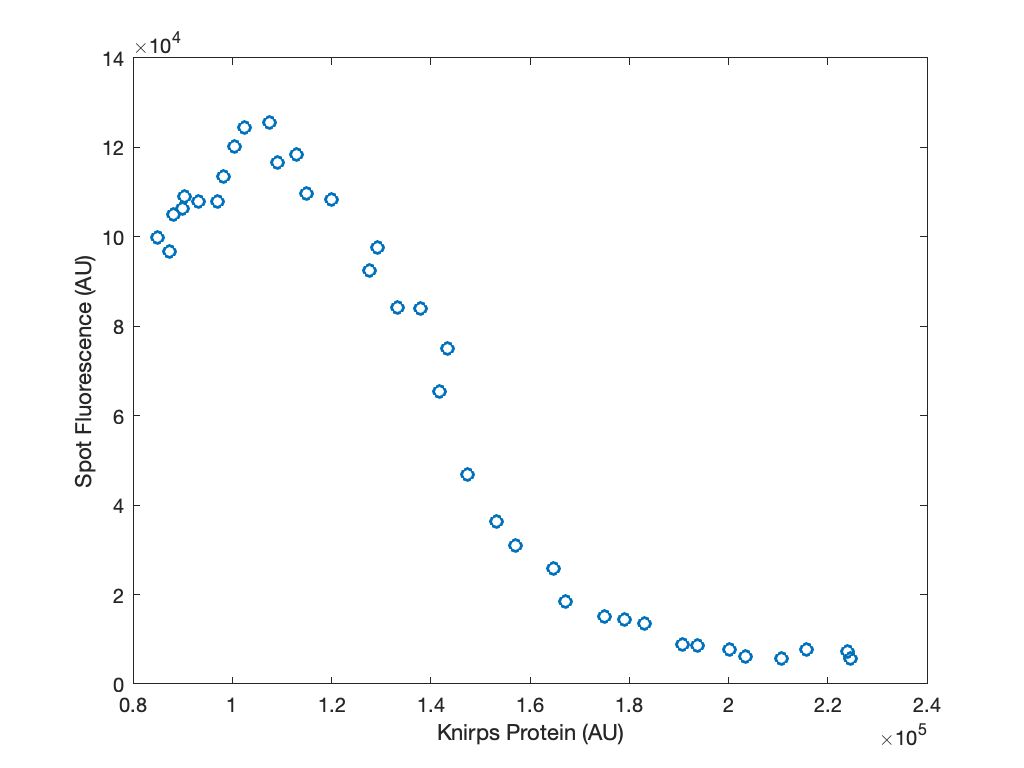

Fig = figure;
plot(ProteinAvr(TimePlotRange),SpotAvr(TimePlotRange),'o','LineWidth',1.5)
xlabel('Knirps Protein (AU)')
ylabel('Spot Fluorescence (AU)')

Next, we will calculate same value for different bins

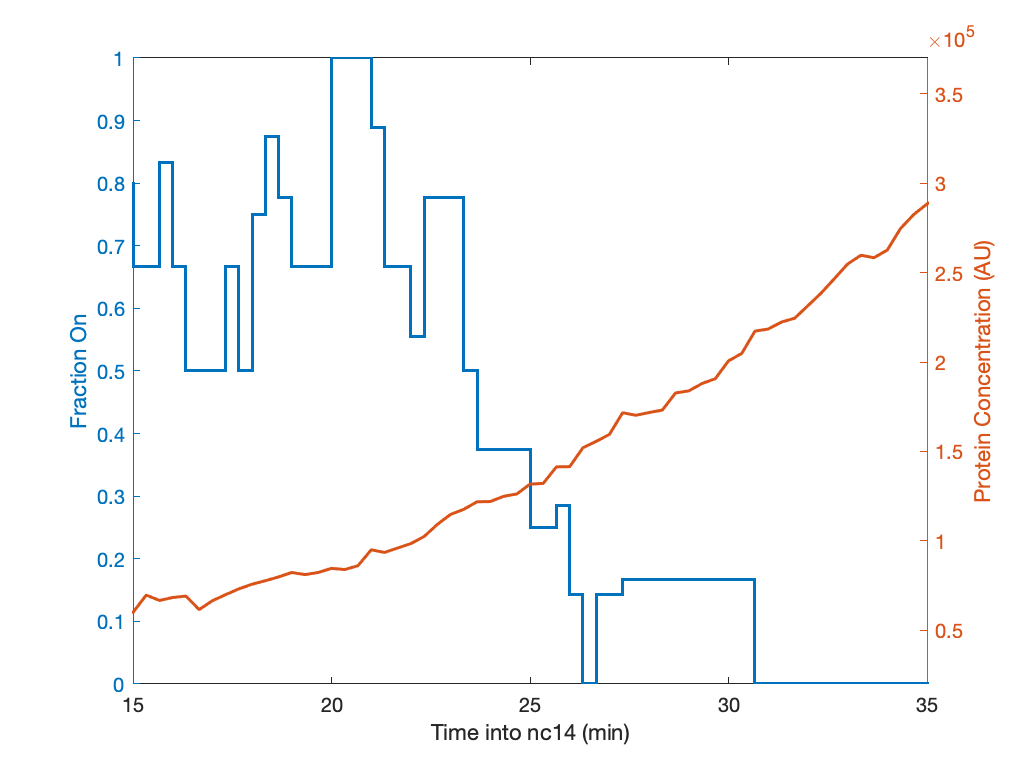

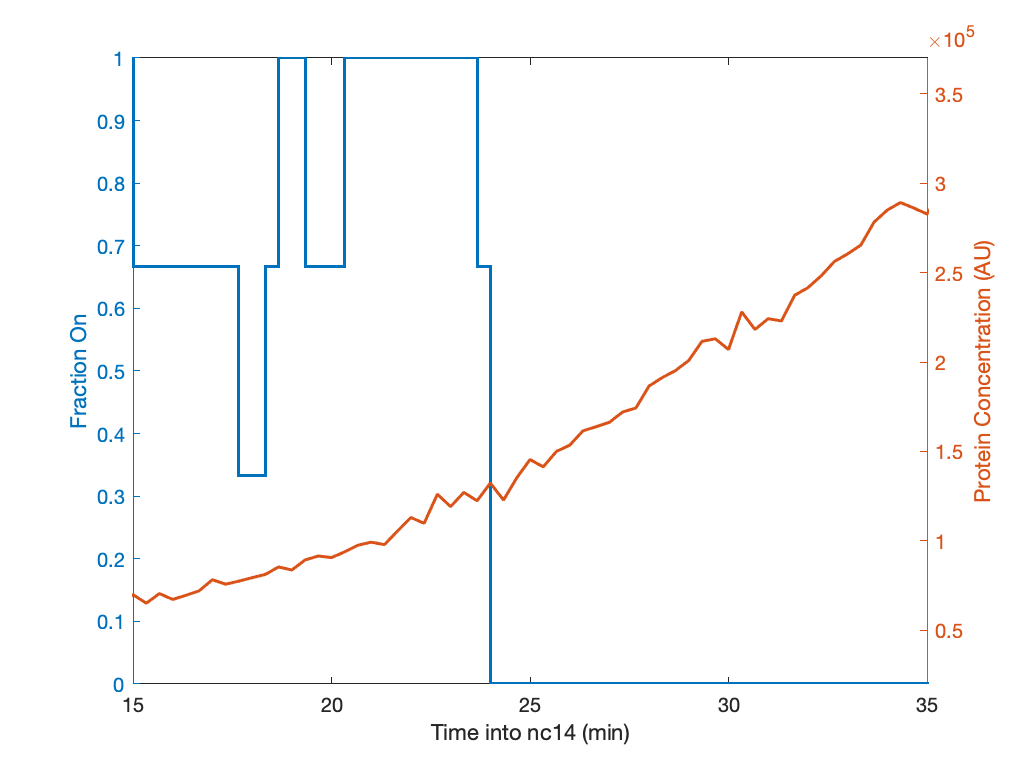

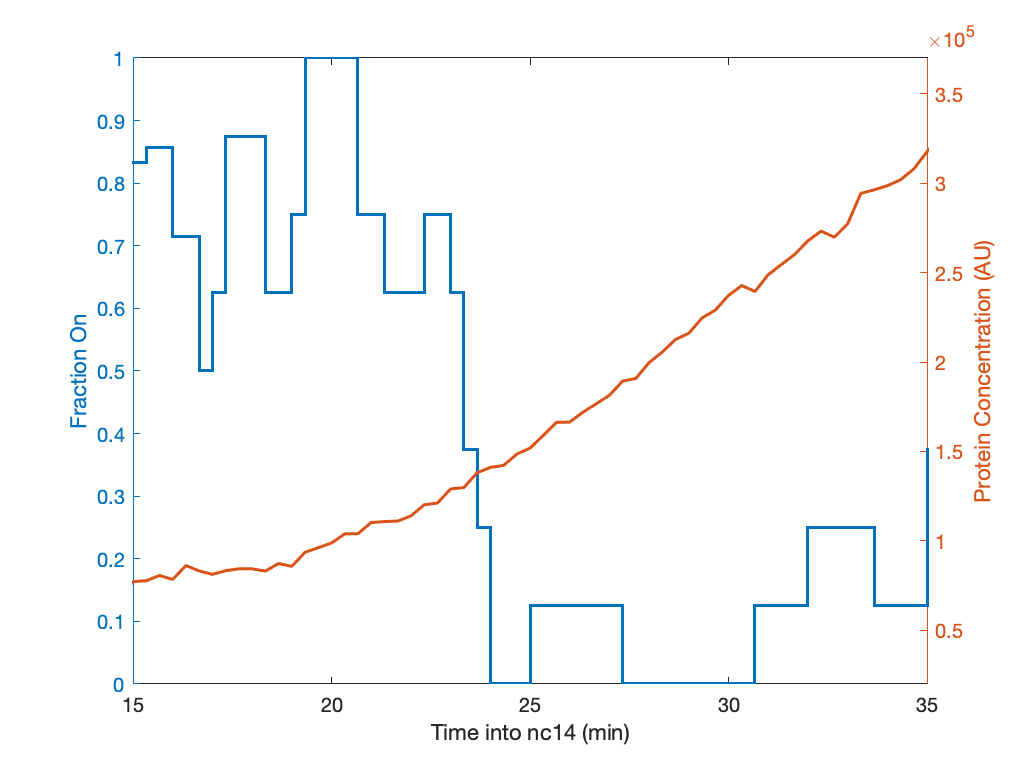

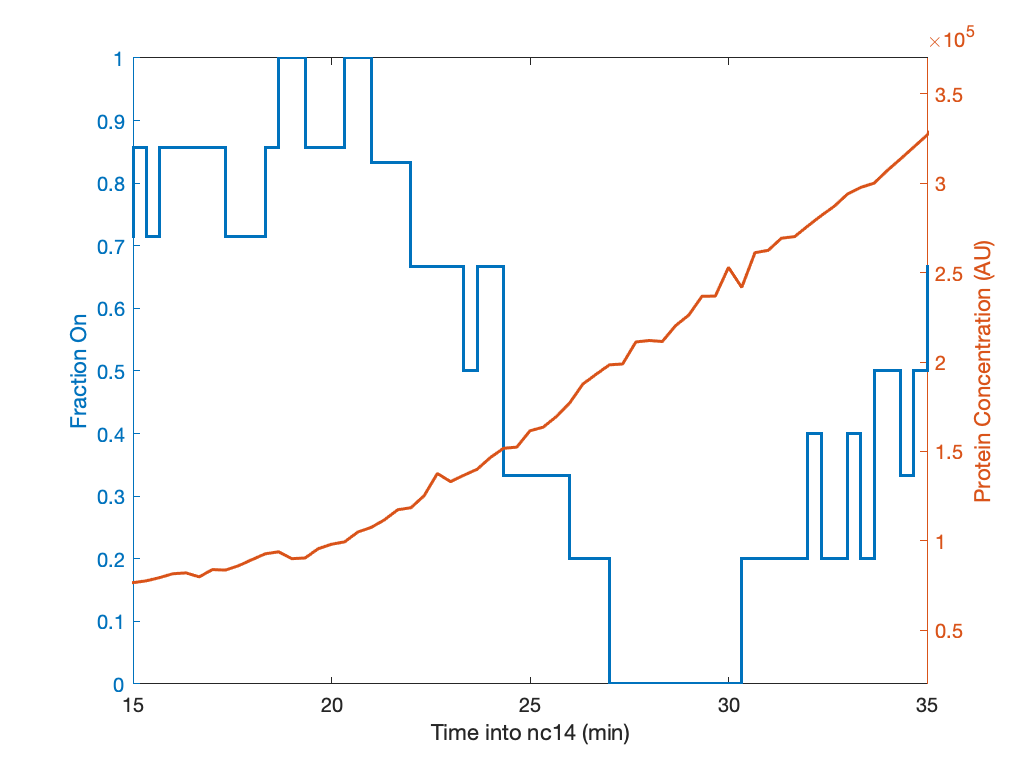

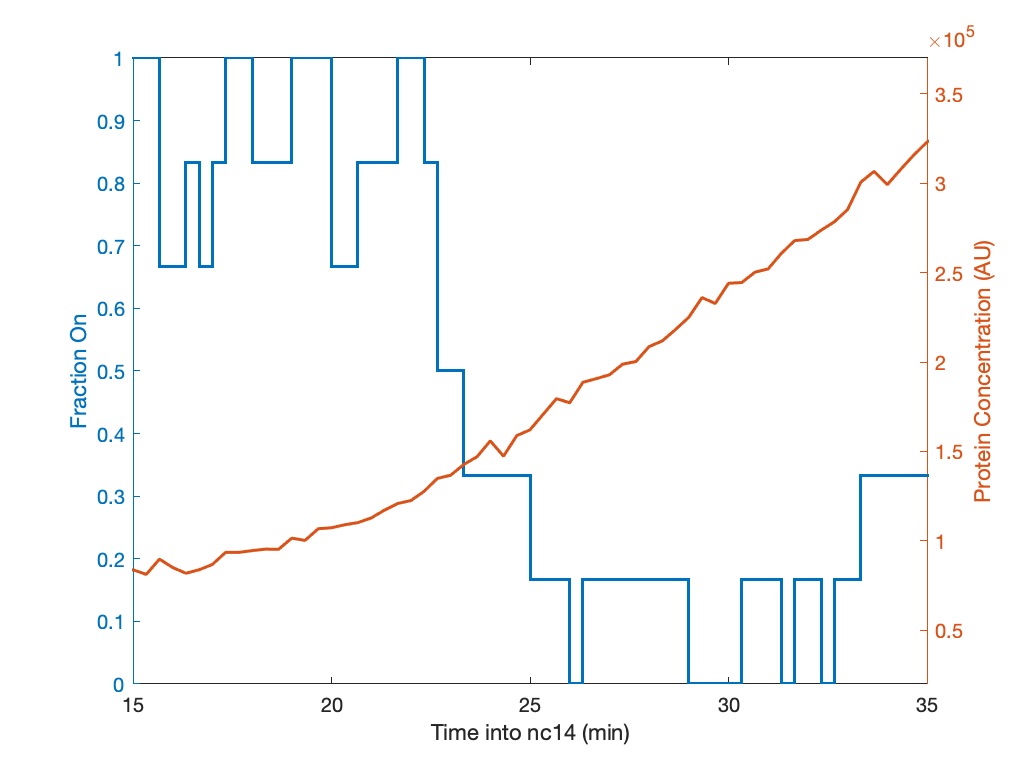

for i = binRange

    % Initialize array for storage
    TotalOn = zeros(1,length(TimeRange));
    TotalTrace = zeros(1,length(TimeRange));
    ProteinTrace = zeros(1,length(TimeRange));
    ProteinSum = zeros(1,length(TimeRange));
    
    TraceIndex = find((SetID_all == dataID) & (ismember(APbinData,i)')); %& QualityFlag');
    
    % compile promoter states and protein concentration
    for j = TraceIndex
        TimePoint = hmm_input_output(j).Time;
        PromoterState = hmm_input_output(j).PromoterState;
        NuclearConc = hmm_input_output(j).NuclearKnirps-offset;
        
        for k = 1:length(TimePoint)
            Index = find(TimeRange==TimePoint(k));
            % compile promoter states
            if PromoterState(k)>2
                TotalOn(Index) = TotalOn(Index)+1;
                TotalTrace(Index) = TotalTrace(Index)+1;
            else
                TotalTrace(Index) = TotalTrace(Index)+1;
            end
            % compile protein concentration
            if ~isnan(NuclearConc(k))
                ProteinSum(Index) = ProteinSum(Index)+NuclearConc(k);
                ProteinTrace(Index) = ProteinTrace(Index)+1;
            end
        end
        
    end
    Fig = figure;
    yyaxis left
    stairs(TimeRange/60,TotalOn./TotalTrace,'LineWidth',1.5)
    ylabel('Fraction On')
    ylim([0 1])
    yyaxis right
    plot(TimeRange/60,ProteinSum./ProteinTrace,'LineWidth',1.5)
    ylabel('Protein Concentration (AU)')
    ylim([2E5 5.5E5]-offset)
    
    xlim([15,35])
    xlabel('Time into nc14 (min)')

end

Calculate input-output function from single particle traces

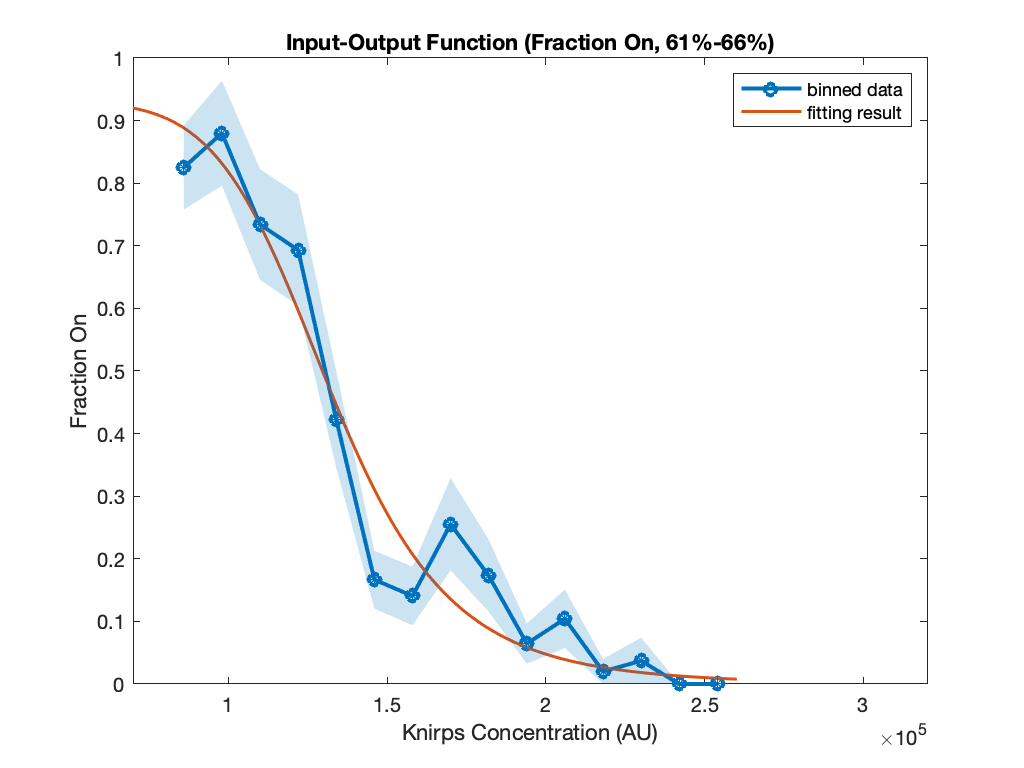

ProteinConc_all = [];
SpotFluo_all = [];
PromoterState_all = [];

TraceIndex = find((SetID_all == dataID) & (ismember(APbinData,binRange)') & QualityFlag');


for i = TraceIndex
    TimePoint = hmm_input_output(i).Time;
    for j = 1:length(TimePoint)
        if (TimePoint(j)<TimeMax) && (TimePoint(j)>TimeMin)
            ProteinConc_all = [ProteinConc_all hmm_input_output(i).NuclearKnirps(j)-offset];
            PromoterState_all = [PromoterState_all (hmm_input_output(i).PromoterState(j)>2)];
            SpotFluo_all = [SpotFluo_all hmm_input_output(i).SpotFluorescence(j)];
        end
    end
end

x = ProteinConc_all';
y = PromoterState_all';
ys = SpotFluo_all';

%edges = quantile(x,len-1);
%edges = [min(x) edges];edges = [edges max(x)]; % add zero and max to left and right hand side of the array
%edges = linspace(min(ProteinConc_all), max(ProteinConc_all),len+1);
[~,~,loc]=histcounts(x,edges);

yplot = accumarray(loc(loc>0),y(loc>0),[len 1])./accumarray(loc(loc>0),1,[len 1]);
yplots = accumarray(loc(loc>0),ys(loc>0),[len 1])./accumarray(loc(loc>0),1,[len 1]);
err = sqrt(accumarray(loc(loc>0),(y(loc>0)).^2,[len 1])./accumarray(loc(loc>0),1,[len 1]))./sqrt(accumarray(loc(loc>0),1,[len 1]));
errs = sqrt(accumarray(loc(loc>0),(ys(loc>0)).^2,[len 1])./accumarray(loc(loc>0),1,[len 1]))./sqrt(accumarray(loc(loc>0),1,[len 1]));

xmid = 0.5*(edges(1:end-1)+edges(2:end));


% generate fit
% specify fit type
fitname = 'a*K^n/(K^n+x^n)';
[io_fit,gof] = fit(xmid(:),yplot(:),fitname,'StartPoint',[3e5,0,0],'Lower',[0,0,0]);
[io_fits,gof] = fit(xmid(:),yplots(:),fitname,'StartPoint',[3e5,1E5,0],'Lower',[0,0,0]);

xRange = double(linspace(min(ProteinConc_all), max(ProteinConc_all)));

fig = figure;
plot(xmid,yplot,'-o','LineWidth',2)
hold on
plot(xRange,io_fit(xRange),'LineWidth',1.5)
boundedline(xmid, yplot, err,'-*','nan', 'gap','alpha','cmap', cmap_temp(1,:));
xlim([2.5E5 5E5]-offset)
ylim([0 1])
xlabel('Knirps Concentration (AU)')
ylabel('Fraction On')
title('Input-Output Function (Fraction On, 61%-66%)')

legend('binned data','fitting result')

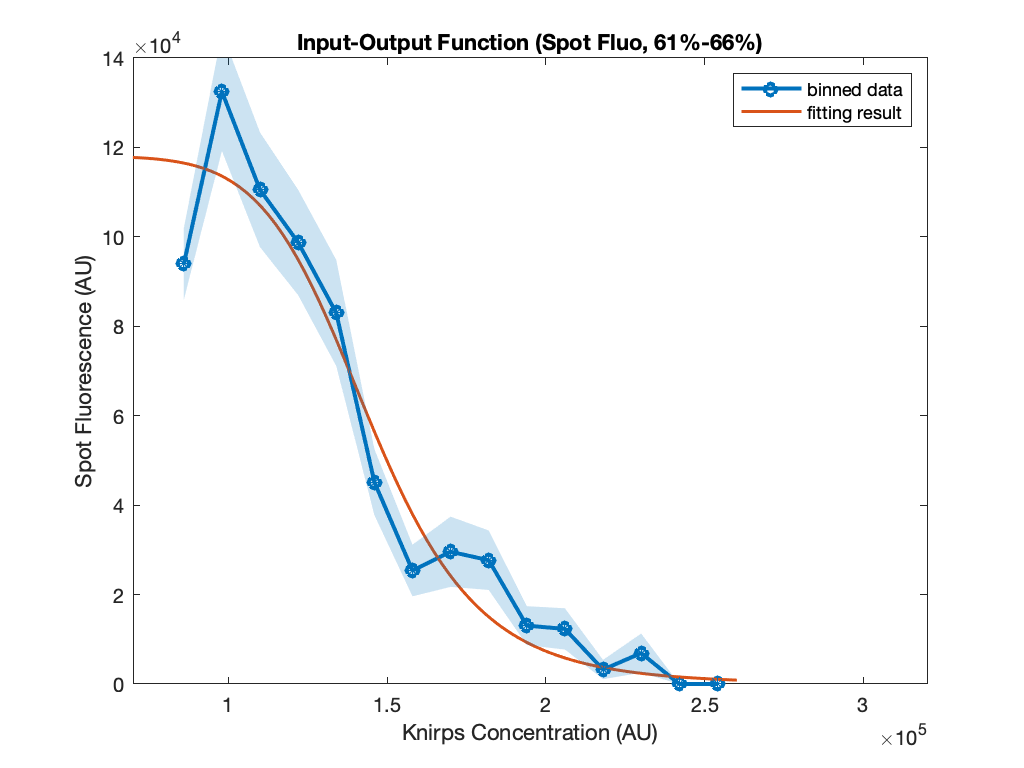

fig = figure;
plot(xmid,yplots,'-o','LineWidth',2)
hold on
plot(xRange,io_fits(xRange),'LineWidth',1.5)
boundedline(xmid, yplots, errs,'-*','nan', 'gap','alpha','cmap', cmap_temp(1,:));
xlim([2.5E5 5E5]-offset)
ylim([0 14E4])
xlabel('Knirps Concentration (AU)')
ylabel('Spot Fluorescence (AU)')
title('Input-Output Function (Spot Fluo, 61%-66%)')

legend('binned data','fitting result')

Try to calculate $k_{on}$ and $k_{off}$

Try to calculate rate with respect to time

%TraceIndex = find((SetID_all == dataID) & (ismember(APbinData,binRange)') & QualityFlag');
TraceIndex = find((SetID_all == dataID) & (ismember(APbinData,binRange)') );

on_duration = [];
on_frame = [];
on_protein = [];
off_duration = [];
off_frame = [];
off_protein = [];

for i = TraceIndex
    TimePoint = hmm_input_output(i).Time;
    PromoterState = hmm_input_output(i).PromoterState;
    NuclearConc = hmm_input_output(i).NuclearKnirps-offset;
    
    initFrame = 1;
    
    for j = 2:length(TimePoint)
        if (PromoterState(j)~= PromoterState(j-1))
            %time = (TimePoint(initFrame) + TimePoint(j))/2/60;
            time = (TimePoint(initFrame))/60;
            %protein = mean(NuclearConc(initFrame:j));
            protein = NuclearConc(initFrame);
            
            %if (time<=30) && (time>=10)
                if PromoterState(j-1)>2
                    on_duration = [on_duration (TimePoint(j)-TimePoint(initFrame))/60];
                    on_frame = [on_frame time];
                    on_protein = [on_protein protein];
                else
                    off_duration = [off_duration (TimePoint(j)-TimePoint(initFrame))/60];
                    off_frame = [off_frame time];
                    off_protein = [off_protein protein];
                end
            %end
            initFrame = j;
        end
    end
end

Calculate

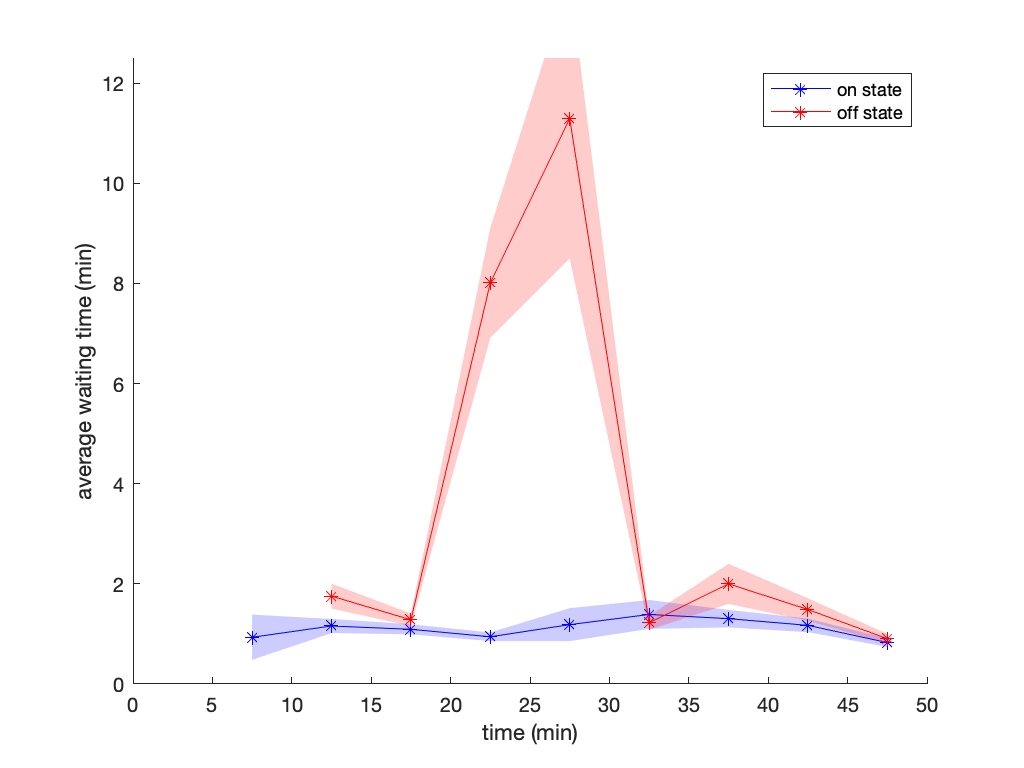


numBin = 10;
edges = linspace(0,50,numBin+1);

x = (edges(1:end-1) + edges(2:end))/2;

bin_off = discretize(off_frame,edges);
[BinValue_off,~,ix_off] = unique(bin_off);
AvgDuration_off = accumarray(ix_off,off_duration,[],@mean);
StdDuration_off = accumarray(ix_off,off_duration,[],@std);
NumDuration_off = accumarray(ix_off,1);

ErrorDuration_off = StdDuration_off./sqrt(NumDuration_off);

bin_on = discretize(on_frame,edges);
[BinValue_on,~,ix_on] = unique(bin_on);
AvgDuration_on = accumarray(ix_on,on_duration,[],@mean);
StdDuration_on = accumarray(ix_on,on_duration,[],@std);
NumDuration_on = accumarray(ix_on,1);

ErrorDuration_on = StdDuration_on./sqrt(NumDuration_on);

flag_off = ~isnan(BinValue_off);
flag_on = ~isnan(BinValue_on);

fig = figure;
p1 = boundedline(x(BinValue_on(flag_on)),AvgDuration_on(flag_on),ErrorDuration_on(flag_on),'-b*','nan', 'gap','alpha');
hold on
p2 = boundedline(x(BinValue_off(flag_off)),AvgDuration_off(flag_off),ErrorDuration_off(flag_off),'-r*','nan', 'gap','alpha');
xlim([0 50])
ylim([0 12.5])
xlabel('time (min)')
ylabel('average waiting time (min)')
legend([p1(1) p2(1)],'on state','off state')

Try to calculate rate with respect to protein concentration

%TraceIndex = find((SetID_all == dataID) & (ismember(APbinData,binRange)') & QualityFlag');
TraceIndex = find((SetID_all == dataID) & (ismember(APbinData,binRange)') );

on_duration = [];
on_frame = [];
on_protein = [];
off_duration = [];
off_frame = [];
off_protein = [];

for i = TraceIndex
    TimePoint = hmm_input_output(i).Time;
    PromoterState = hmm_input_output(i).PromoterState;
    NuclearConc = hmm_input_output(i).NuclearKnirps-offset;
    
    initFrame = 1;
    
    for j = 2:length(TimePoint)
        if (PromoterState(j)~= PromoterState(j-1))
            %time = (TimePoint(initFrame) + TimePoint(j))/2/60;
            time = (TimePoint(initFrame))/60;
            %protein = mean(NuclearConc(initFrame:j));
            protein = NuclearConc(initFrame);
            
            if (time<=30) && (time>=10)
                if PromoterState(j-1)>2
                    on_duration = [on_duration (TimePoint(j)-TimePoint(initFrame))/60];
                    on_frame = [on_frame time];
                    on_protein = [on_protein protein];
                else
                    off_duration = [off_duration (TimePoint(j)-TimePoint(initFrame))/60];
                    off_frame = [off_frame time];
                    off_protein = [off_protein protein];
                end
            end
            initFrame = j;
        end
    end
end


Calculate

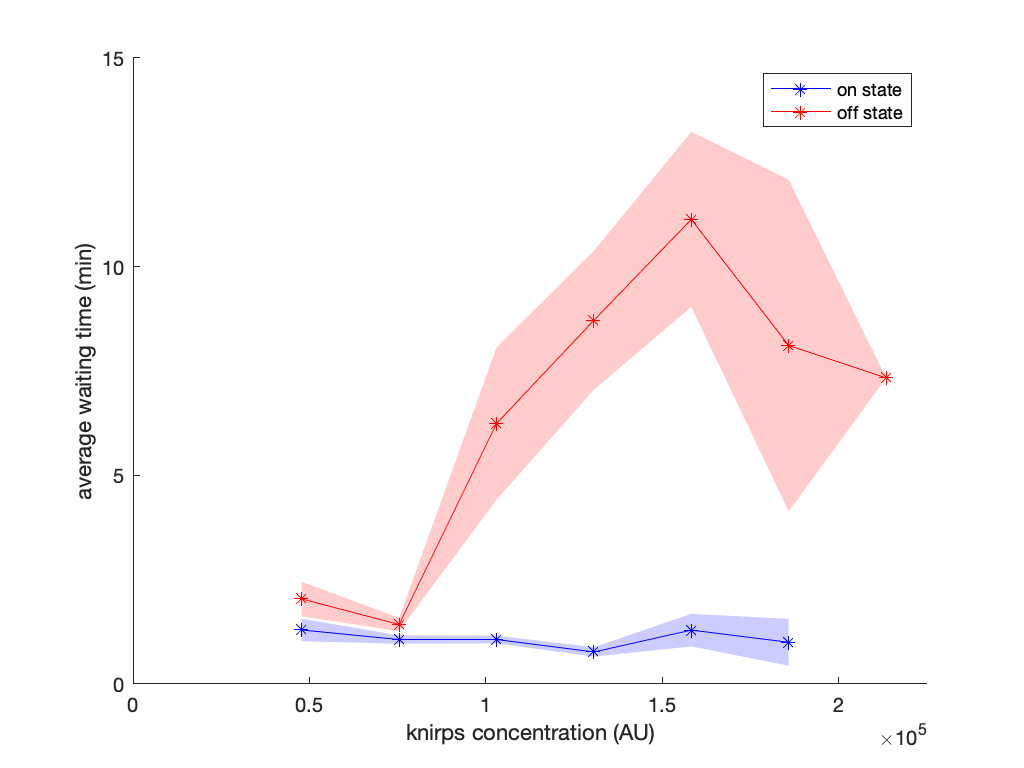

numBin = 10;
edges_protein = linspace(3.4E4,3.1E5,numBin+1);
x = (edges_protein(1:end-1) + edges_protein(2:end))/2;

bin_off_protein = discretize(off_protein,edges_protein);
[BinValue_off_protein,~,ix_off_protein] = unique(bin_off_protein);
AvgDuration_off_protein = accumarray(ix_off_protein,off_duration,[],@mean);
StdDuration_off_protein = accumarray(ix_off_protein,off_duration,[],@std);
NumDuration_off_protein = accumarray(ix_off_protein,1);

ErrorDuration_off_protein = StdDuration_off_protein./sqrt(NumDuration_off_protein);

bin_on_protein = discretize(on_protein,edges_protein);
[BinValue_on_protein,~,ix_on_protein] = unique(bin_on_protein);
AvgDuration_on_protein = accumarray(ix_on_protein,on_duration,[],@mean);
StdDuration_on_protein = accumarray(ix_on_protein,on_duration,[],@std);
NumDuration_on_protein = accumarray(ix_on_protein,1);

ErrorDuration_on_protein = StdDuration_on_protein./sqrt(NumDuration_on_protein);

flag_off_protein = ~isnan(BinValue_off_protein);
flag_on_protein = ~isnan(BinValue_on_protein);

%{
fig = figure;
subplot(1,2,1)
boundedline(edges(BinValue_on_protein(flag_on)),AvgDuration_on_protein(flag_on),ErrorDuration_on_protein(flag_on))
%plot(edges(BinValue_on_protein(flag_on)),AvgDuration_on_protein(flag_on),'-o')
xlim([0 2.5]*1E5)
ylim([0 15])
xlabel('knirps concentration (AU)')
ylabel('average duration (min)')

subplot(1,2,2)
boundedline(edges(BinValue_off_protein(flag_off)),AvgDuration_off_protein(flag_off),ErrorDuration_off_protein(flag_off))
xlim([0 2.5]*1E5)
ylim([0 15])
xlabel('knirps concentration (AU)')
ylabel('average duration (min)')
%}

fig = figure;
p1 = boundedline(x(flag_on_protein),AvgDuration_on_protein(flag_on_protein),ErrorDuration_on_protein(flag_on_protein),'-b*','nan', 'gap','alpha');
hold on
p2 = boundedline(x(flag_off_protein),AvgDuration_off_protein(flag_off_protein),ErrorDuration_off_protein(flag_off_protein),'-r*','nan', 'gap','alpha');
xlim([0 2.25]*1E5)
ylim([0 15])
xlabel('knirps concentration (AU)')
ylabel('average waiting time (min)')
legend([p1(1) p2(1)],'on state','off state')